# Multivariable Functions

They are just functions with more than one variable. The notation is simple:


$$z=f\left(x,y\right)\;\mathrm{or}\;z=f\left(x_1 ,x_2 ,x_3 ,\ldotp \ldotp \ldotp \right)$$


What about the domain and range of these new type of functions? El dominio responde a que valores puede tomar las variables independientes y el rango responde a que valores puede devolver. Supongamos que z = f(x,y) tenemos 2 variables independientes y una dependiente (una grafica 3D) entonces nuestro dominio vendria a ser todos los puntos (x,y) en los cuales z exista, es decir una region en el espacio dentro del plano xy. Y el rango son todos los valores que z puede tomar (una lista de numeros). Existen diferentes tipos de funciones donde la salida puede ser de 2 o 3 numeros (funciones vectoriales).

Supongamos que:


$$\begin{array}{l}
z=\sqrt{y-x^2 };\\
\mathrm{Domain}=y\ge x^2 \\
\mathrm{Range}=\left\lbrack 0,\infty \right\rbrack 
\end{array}$$


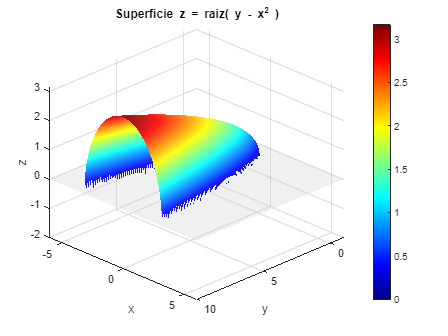

% Rango de x y y ampliado
x = linspace(-6, 6, 500);    % más puntos para suavidad
y = linspace(-1, 10, 500);

% Crear la malla
[X, Y] = meshgrid(x, y);

% Calcular la función solo donde existe
Z = sqrt(Y - X.^2);
Z(Y < X.^2) = NaN; % fuera del dominio no se dibuja

% Graficar la superficie
figure
surf(X, Y, Z, Z, 'EdgeColor','none') % colores según Z
colormap(jet)                        
colorbar                             
shading interp                       
alpha(0.9)                            
hold on

% Plano base en z=0
Z0 = zeros(size(X));
Z0(~isnan(Z)) = 0; 
surf(X, Y, Z0, 'FaceColor',[0.8 0.8 0.8], 'FaceAlpha',0.3, 'EdgeColor','none')

% Etiquetas y título
xlabel('x')
ylabel('y')
zlabel('z')
title('Superficie z = raiz( y - x^2 )')

% Limites de los ejes (ahora con Z negativo opcional)
xlim([-6 6])
ylim([-1 10])
zlim([-2 max(Z(:))])  % eje Z negativo

% Invertir el eje Y
set(gca, 'YDir','reverse')

% Vista y cuadrícula
view(45,30)
grid on

Esa es la grafica de nuestra funcion z, el dominio en la grafica vendria a ser una region ( una parabola y la region dentro de esta) puedes verlo claramente, porque solo para esos puntos z existe y en los otros puntos no. Ademas podemos observar que z solo puede ser positivo, debido a la naturaleza de la que esta compuesta.